# 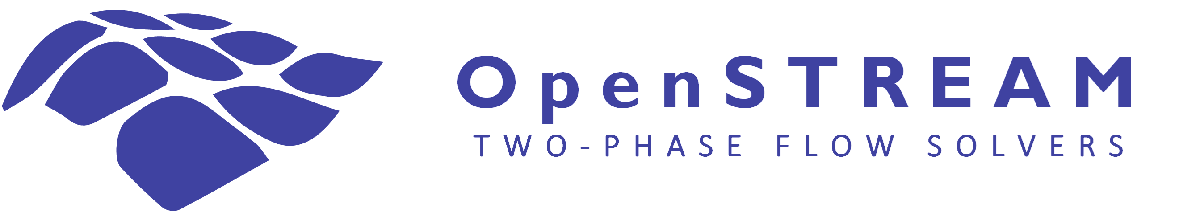

# Tutorial #4: Three-field solver capabilities

In this tutorial, you will explore capabilities specific to the OpenSTREAM three-field solver. The solver uses the mixture-model vapor solution and separates the liquid into a film field and an entrained-droplet field in the annular-flow region. It calculates film transport, droplet transport, evaporation, entrainment, deposition, and field velocities.

The selected geometry consists of a 3.5 m uniformly heated vertical tube with an inner diameter of 8.8 mm, followed by a 2 m adiabatic section with the same diameter. The flow enters slightly subcooled, reaches annular flow, and undergoes film depletion in the heated section. In the adiabatic section, droplet deposition can regenerate the film.

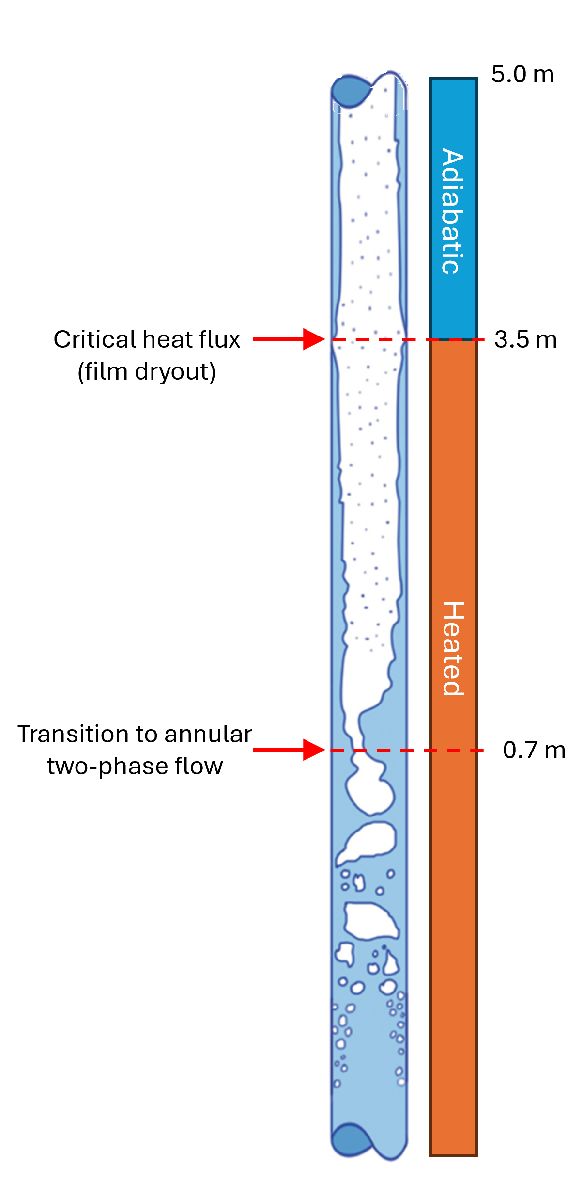

Learning objectives:

- Input files and three-field model sets

- Default three-field calculation

- Film and droplet mass transport

- Film thickness and film flow per unit perimeter

- Onset-of-annular-flow initialization

- Film and droplet momentum models

- Entrainment and deposition closure models

- Film and droplet momentum exchanges

- Pseudo-time convergence history

- Physical transient calculation

*Note: This tutorial is designed for use with output displayed inline (View > Output Inline) in the MATLAB Live Editor. Any animations are displayed in separate pop-up figure windows and can be played continuously or inspected one stored time step at a time. Animations and their controls are not preserved in static Markdown, HTML, or PDF exports.*

**Important**

*The physical models and closure relations selected in this tutorial are used for educational and demonstration purposes. Their use does not imply that they are appropriate, recommended, or validated for the simulated conditions. The calculated results should therefore be interpreted as illustrations of the solver framework and its capabilities, rather than as validated predictions. Before applying OpenSTREAM to a technical study, assess the assumptions, applicability range, and validation basis of every selected model.*

## Set up the MATLAB path

Clear existing variables from the workspace.

clearvars

When this tutorial is run directly from the tutorials folder, the OpenSTREAM root directory is one level above the current folder.

osp = './..';
addpath(osp);

## Input files

Import the required packages.

import Inputs.*
import Solvers.*
import Solvers.Mixture.*
import Solvers.ThreeField.*

Display the model file and locate the TUTORIAL4 entries.

type('../inputs/models.inp')

The tutorial uses the following model sets:

- TUTORIAL4A uses the documented three-field defaults.

- TUTORIAL4B prescribes a droplet-to-liquid mass ratio of 0.30 at the onset of annular flow.

- TUTORIAL4C uses equilibrium film and droplet momentum models.

- TUTORIAL4D solves the full film and droplet momentum equations.

- TUTORIAL4E uses the GOVAN entrainment and deposition model pair.

- TUTORIAL4F disables entrainment and deposition to isolate film evaporation.

The deposition and entrainment models are coupled closure relations. When comparing model families, use a consistent pair.

Display the options, geometry, and steady-state boundary conditions.

type('../inputs/options.inp')
type('../inputs/geom.inp')
type('../inputs/tutorial1.inp')

## Default three-field calculation

Construct TUTORIAL4A. Warnings are temporarily suppressed to keep the tutorial concise. During development, leaving warnings enabled is recommended.

% Construct the inputSet.
warning off
inputSetA = InputSet( ...
    modelFilePath          = [osp '/inputs/models.inp'], ...
    modelID                = 'TUTORIAL4A', ...
    optionsFilePath        = [osp '/inputs/options.inp'], ...
    optionsID              = 'DEFAULT', ...
    geometryFilePath       = [osp '/inputs/geom.inp'], ...
    geometryID             = 'TUTORIAL1', ...
    bcFilePath             = [osp '/inputs/tutorial1.inp'], ...
    sessionParentDir       = fullfile(pwd,'outputs'), ...
    overwriteSessionFiles = true, ...
    LOGMODE                = 'BOTH');
warning on

The three-field solver requires a solved mixture solution. If one is not supplied, the constructor creates and solves it automatically.

% Create the three-field solver.
tfSolverA = ThreeFieldSolver(inputSetA);

Inspect the initialized solver. The liquid-film and droplet fields are stored in separate objects, while the solved mixture solver is retained by the three-field solver. The three-field solver calculates the film and droplet fields separately but reuses the vapor-field solution from the mixture solver.

disp(tfSolverA)
% Solve the three-field solver.
tfSolverA.solve();

Note: The plot marks the onset of annular flow and, by default, displays the separate film and droplet quantities only in the annular-flow region.

Plot the field mass flow rates.

tfSolverA.plotz('display','W','resize',1);

The total liquid mass flow rate is divided between the film and entrained droplets, while the vapor-field solution is retained from the mixture solver.

It can be observed that complete film dryout occurs at the end of the heated section, at an elevation of 3.5 m. In the downstream adiabatic section, droplet deposition regenerates the liquid film, resulting in a progressive recovery of the film mass flow rate.

Plot the field velocities.

tfSolverA.plotz('display','U','resize',1);

The liquid film, entrained droplets, and vapor can generally travel at different velocities. In the default configuration, the droplet momentum model prescribes a droplet-to-vapor velocity ratio of one. The droplet momentum conservation equation is therefore not solved, and the droplet velocity is set equal to the vapor velocity. The film velocity is calculated using an algebraic model and is substantially lower than the vapor and droplet velocities. This behavior is consistent with annular flow, in which wall shear retards the liquid film. Note that the full momentum conservation equations for the droplet and film fields will be solved in TUTORIAL4D.

Plot the film flow per unit perimeter (WL) and film thickness.

tfSolverA.plotz( ...
    'display', {'WL','THICK'}, ...
    'arrangement', 'horizontal', ...
    'resize', 1);

The film mass flow rate per unit wall perimeter, WL, is useful for comparing film transport independently of the wall perimeter. Film thickness combines the effects of film mass flow rate, velocity, and liquid density and therefore provides a complementary geometrical measure of the local film inventory, corresponding to the liquid volume per unit wall area.

Plot mixture qualities and void fraction together with the film and bulk-droplet mass-quality indicators.

tfSolverA.plotz( ...
    'display', 'VR', ...
    'nearWall', true, ...
    'resize', 1);

Save the solver object if desired.

tfSolverA.save('name','tfSolverA','showpath',false);

### Film mass exchanges

Plot deposition, entrainment, evaporation, and the total film mass exchange.

tfSolverA.plotz('display','FWE','resize',1);

The FWE plot shows the individual mass-exchange mechanisms acting on the film field. Droplet deposition transfers liquid from the entrained-droplet field to the film and therefore contributes positively. Entrainment transfers liquid from the film to the droplet field, while evaporation converts liquid from the film into vapor, transferring mass from the liquid-film field to the vapor field. Both contributions are therefore negative according to the film sign convention.

The total film mass-exchange rate is the sum of the deposition, entrainment, and evaporation contributions. A negative total indicates net film depletion, whereas a positive total indicates net film regeneration. In this simulation, the heated section is dominated by film depletion. Downstream of the heated section, evaporation ceases and continuing droplet deposition produces a positive total mass-exchange rate, progressively regenerating the film. Along the downstream adiabatic section, the total film mass-exchange rate progressively approaches zero, as expected for a system relaxing toward its equilibrium state.

## Onset-of-annular-flow initialization

By default, OAFENTRAINED = EQUILIBRIUM determines the initial split by balancing deposition and entrainment. TUTORIAL4B instead prescribes a droplet-to-liquid mass ratio of 0.30.

% Construct the inputSet.
warning off
inputSetB = InputSet( ...
    modelFilePath          = [osp '/inputs/models.inp'], ...
    modelID                = 'TUTORIAL4B', ...
    optionsFilePath        = [osp '/inputs/options.inp'], ...
    optionsID              = 'DEFAULT', ...
    geometryFilePath       = [osp '/inputs/geom.inp'], ...
    geometryID             = 'TUTORIAL1', ...
    bcFilePath             = [osp '/inputs/tutorial1.inp'], ...
    sessionParentDir       = fullfile(pwd,'outputs'), ...
    overwriteSessionFiles = true, ...
    LOGMODE                = 'BOTH');
warning on

% Create the three-field solver.
tfSolverB = ThreeFieldSolver(inputSetB);
% Solve the three-field solver.
tfSolverB.solve();

Plot field mass flow rates and film mass exchanges.

tfSolverB.plotz( ...
    'display', {'W','FWE'}, ...
    'arrangement', 'horizontal', ...
    'resize', 1);

Compare the prescribed-ratio result with the equilibrium initialization used in TUTORIAL4A. At the onset of annular flow, the imposed droplet-to-liquid mass ratio of 0.3 is clearly visible: the droplet mass flow rate is exactly 30% of the total liquid mass flow rate, while the remaining 70% is assigned to the film.

Farther downstream, the film and droplet mass conservation equations, together with entrainment, deposition, and evaporation, progressively redistribute mass among the film, droplet, and vapor fields. Consequently, the influence of the prescribed initial film-droplet split diminishes as the solution develops along the channel.

## Equilibrium momentum models

TUTORIAL4C selects local equilibrium force-balance models for the film and droplet velocities.

% Construct the inputSet.
warning off
inputSetC = InputSet( ...
    modelFilePath          = [osp '/inputs/models.inp'], ...
    modelID                = 'TUTORIAL4C', ...
    optionsFilePath        = [osp '/inputs/options.inp'], ...
    optionsID              = 'DEFAULT', ...
    geometryFilePath       = [osp '/inputs/geom.inp'], ...
    geometryID             = 'TUTORIAL1', ...
    bcFilePath             = [osp '/inputs/tutorial1.inp'], ...
    sessionParentDir       = fullfile(pwd,'outputs'), ...
    overwriteSessionFiles = true, ...
    LOGMODE                = 'BOTH');
warning on

% Create the three-field solver.
tfSolverC = ThreeFieldSolver(inputSetC);
% Solve the three-field solver.
tfSolverC.solve();

Plot field velocities, film momentum exchanges and drop momentum exchanges.

tfSolverC.plotz( ...
    'display', {'U','FME','DME'}, ...
    'resize', 1);

The equilibrium velocity models determine the film and droplet velocities by satisfying a local force balance. The film and droplet momentum-exchange plots show the individual terms contributing to these balances. As expected, the total momentum-exchange term is approximately zero everywhere for both fields, within the numerical convergence tolerance.

The calculated droplet-velocity distribution is less smooth than that obtained using the full momentum formulation. Because the equilibrium model neglects temporal and axial momentum inertia, the local droplet velocity responds directly to changes in the force-balance terms and is not smoothed by momentum transport from neighboring axial locations or preceding time steps.

## Full momentum equations

TUTORIAL4D solves the full film and droplet momentum equations.

% Construct the inputSet.
warning off
inputSetD = InputSet( ...
    modelFilePath          = [osp '/inputs/models.inp'], ...
    modelID                = 'TUTORIAL4D', ...
    optionsFilePath        = [osp '/inputs/options.inp'], ...
    optionsID              = 'DEFAULT', ...
    geometryFilePath       = [osp '/inputs/geom.inp'], ...
    geometryID             = 'TUTORIAL1', ...
    bcFilePath             = [osp '/inputs/tutorial1.inp'], ...
    sessionParentDir       = fullfile(pwd,'outputs'), ...
    overwriteSessionFiles = true, ...
    LOGMODE                = 'BOTH');
warning on

% Create the three-field solver.
tfSolverD = ThreeFieldSolver(inputSetD);
% Solve the three-field solver.
tfSolverD.solve();

Plot field velocities, film momentum exchanges and drop momentum exchanges.

tfSolverD.plotz( ...
    'display', {'U','FME','DME'}, ...
    'resize', 1);

Compare the full-momentum results with the equilibrium-model results obtained in TUTORIAL4C. In the equilibrium models, the film and droplet velocities are determined independently at each axial location by requiring the total local momentum-exchange term to be zero. The full formulations instead retain spatial momentum transport, allowing an imbalance in the local momentum-exchange terms to accelerate or decelerate the fields along the channel. This inertial coupling between neighboring axial locations generally produces smoother velocity distributions.

## Entrainment and deposition model family

TUTORIAL4E selects the GOVAN model for both entrainment and deposition, instead of the default OKAWA2003 and OKAWA models.

% Construct the inputSet.
warning off
inputSetE = InputSet( ...
    modelFilePath          = [osp '/inputs/models.inp'], ...
    modelID                = 'TUTORIAL4E', ...
    optionsFilePath        = [osp '/inputs/options.inp'], ...
    optionsID              = 'DEFAULT', ...
    geometryFilePath       = [osp '/inputs/geom.inp'], ...
    geometryID             = 'TUTORIAL1', ...
    bcFilePath             = [osp '/inputs/tutorial1.inp'], ...
    sessionParentDir       = fullfile(pwd,'outputs'), ...
    overwriteSessionFiles = true, ...
    LOGMODE                = 'BOTH');
warning on

% Create the three-field solver.
tfSolverE = ThreeFieldSolver(inputSetE);
% Solve the three-field solver.
tfSolverE.solve();

Plot field mass flow rates, film thickness and film mass exchanges.

tfSolverE.plotz( ...
    'display', {'W','THICK','FWE'}, ...
    'resize', 1);

Compare these results with those obtained using the default closure models in TUTORIAL4A to examine how the selected coupled entrainment and deposition model family affects the distribution of liquid between the film and entrained-droplet fields.

Although the film approaches complete dryout near the end of the heated section, as it does with the default models, the axial distribution of the film mass flow rate is substantially different. In particular, the onset-of-annular-flow equilibrium initialization associated with the GOVAN entrainment and deposition models predicts a very small droplet mass flow rate at the onset of annular flow. Most of the liquid is therefore initially assigned to the film field.

Farther downstream, entrainment, deposition, and evaporation progressively modify this initial field distribution, leading to a film-dryout condition near the end of the heated section despite the different upstream evolution.

## Evaporation-only reference

TUTORIAL4F disables entrainment and deposition. Film evaporation remains, providing a useful reference for isolating phase-change-driven film depletion.

% Construct the inputSet.
warning off
inputSetF = InputSet( ...
    modelFilePath          = [osp '/inputs/models.inp'], ...
    modelID                = 'TUTORIAL4F', ...
    optionsFilePath        = [osp '/inputs/options.inp'], ...
    optionsID              = 'DEFAULT', ...
    geometryFilePath       = [osp '/inputs/geom.inp'], ...
    geometryID             = 'TUTORIAL1', ...
    bcFilePath             = [osp '/inputs/tutorial1.inp'], ...
    sessionParentDir       = fullfile(pwd,'outputs'), ...
    overwriteSessionFiles = true, ...
    LOGMODE                = 'BOTH');
warning on

% Create the three-field solver.
tfSolverF = ThreeFieldSolver(inputSetF);
% Solve the three-field solver.
tfSolverF.solve();

Plot field mass flow rates, film thickness and film mass exchanges.

tfSolverF.plotz( ...
    'display', {'W','THICK','FWE'}, ...
    'resize', 1);

With deposition and entrainment disabled, evaporation is the only mass-exchange mechanism acting on the liquid film. The film mass-exchange plot therefore isolates the effect of evaporation on the film mass flow rate and thickness. Under the thermal-equilibrium assumption, the film evaporation rate is directly proportional to the applied wall heat flux and becomes zero downstream of the heated section.

### Pseudo-time convergence history

The filmInit and dropInit arrays store the pseudo-time iterations used to obtain the initial steady-state solution. The NULL solve mode displays this convergence history rather than a physical transient.

tfSolverD.plotz( ...
    [], ...
    'display', {'W','U','THICK'}, ...
    'solveMode', 'NULL', ...
    'resize', 1);

Plot the pseudo-time histories at the outlet.

tfSolverD.plott( ...
    tfSolverD.NZ, ...
    'display', {'W','U','THICK'}, ...
    'solveMode', 'NULL', ...
    'resize', 1);

Tutorial 7 explains the interpretation of pointwise and temporal convergence in greater detail.

## Physical transient calculation

Reuse TUTORIAL4D with the existing power-transient boundary conditions.

type('../inputs/tutorial2_transient.inp')
% Construct the inputSet.
warning off
inputSetG = InputSet( ...
    modelFilePath          = [osp '/inputs/models.inp'], ...
    modelID                = 'TUTORIAL4D', ...
    optionsFilePath        = [osp '/inputs/options.inp'], ...
    optionsID              = 'DEFAULT', ...
    geometryFilePath       = [osp '/inputs/geom.inp'], ...
    geometryID             = 'TUTORIAL1', ...
    bcFilePath             = [osp '/inputs/tutorial2_transient.inp'], ...
    sessionParentDir       = fullfile(pwd,'outputs'), ...
    overwriteSessionFiles = true, ...
    LOGMODE                = 'BOTH');
warning on

% Create the three-field solver.
tfSolverG = ThreeFieldSolver(inputSetG);

The constructor automatically creates and solves the corresponding transient mixture solver, which supplies the initial state and pressure gradient for every physical time step.

% Solve the three-field solver.
tfSolverG.solve();

Plot selected axial distributions for all stored physical times. Multiple time indices produce an animated axial plot.

tfSolverG.plotz( ...
    [], ...
    'display', {'HFLUX','W','THICK','FWE'}, ...
    'resize', 1);

Plot the physical-time response at the channel outlet.

tfSolverG.plott( ...
    tfSolverG.NZ, ...
    'display', {'HFLUX','W','THICK','FWE'}, ...
    'resize', 1);

Following the transient power decrease, the calculated liquid-film mass flow rate and film thickness increase. This behavior is consistent with the reduction in wall evaporation.

## Summary

In this tutorial, you examined film and droplet transport, film thickness, onset-of-annular-flow initialization, alternative momentum formulations, entrainment and deposition closures, field momentum exchanges, pseudo-time convergence, and a physical transient using the OpenSTREAM three-field solver.